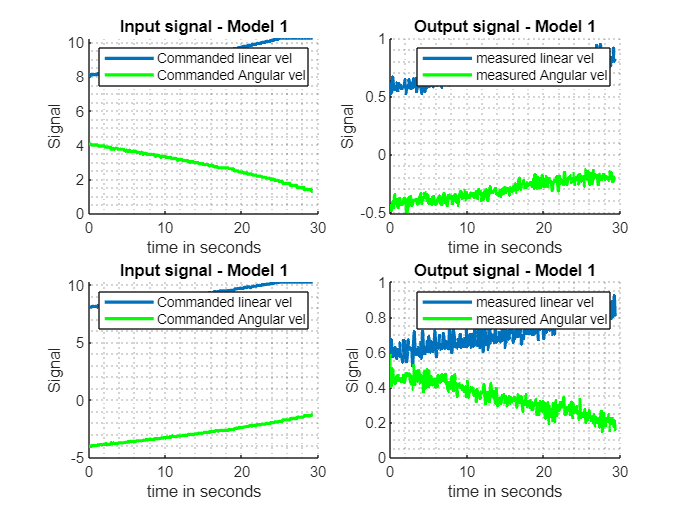

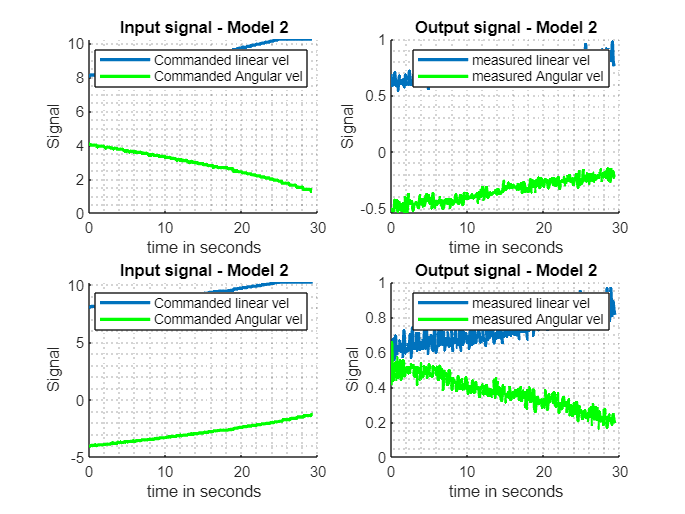

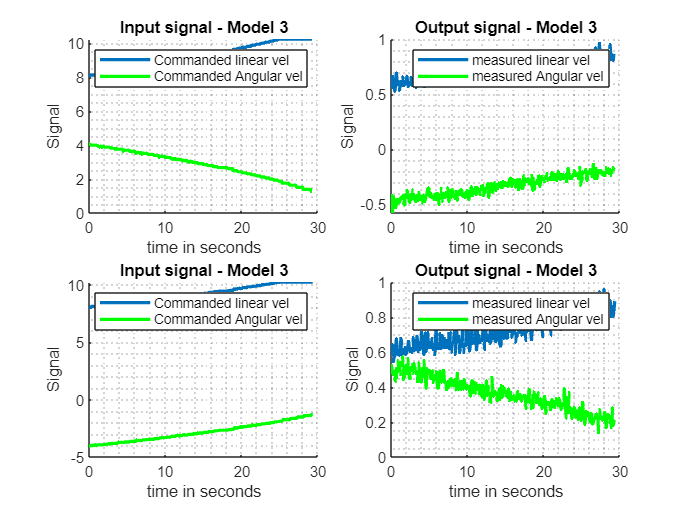

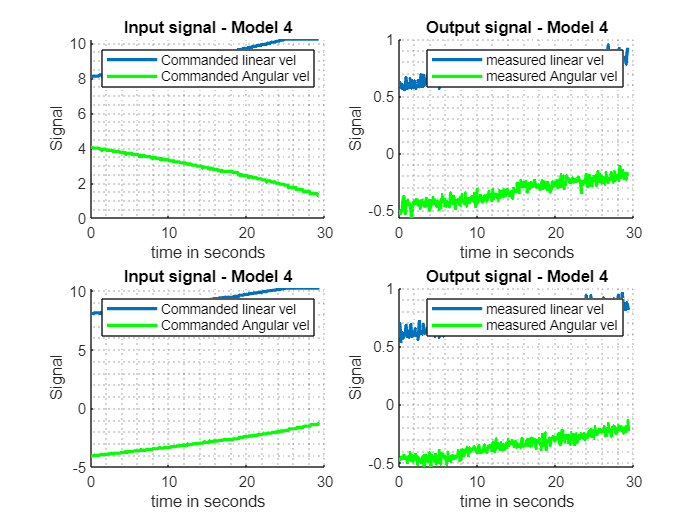

%% Interacting Mixing Model approach for off road navigation
%%% We have four different models to capture the uncertain parameters

%%% Wheel angular velocities are transformed to body velcoity and angular
%%% velocity

clc; clear; 

generate_input_output_data


% Model 1 
K1 = 0.0763; M1 = 0.1134;

% Model 2 
K2 = 0.0784; M2 = 0.1257;

% Model 3 
K3 = 0.0776; M3 = 0.1196;

% Model 4 
K4 = 0.0774; M4 = 0.1216;
% Transitional probability matrix 
P_tran = [0.85 0.05 0.05 0.05;
                          0.05 0.85 0.05 0.05;
                          0.05 0.05 0.85 0.05;
                          0.05 0.05 0.05 0.85]; 


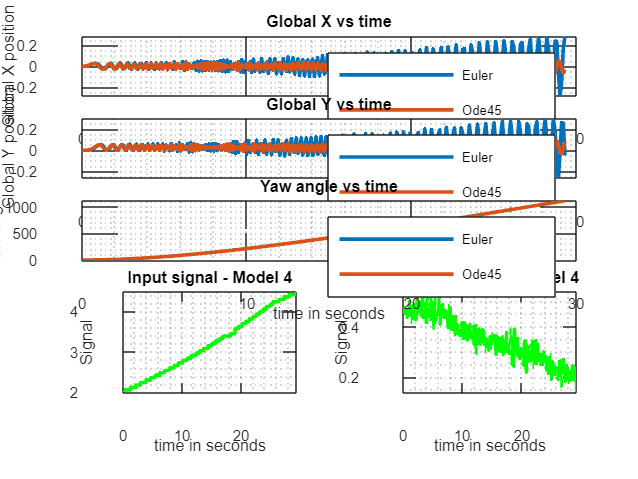


% noise information
n = 5; % Five states -- Global X coordinate, Global Y coordinate, yaw angle, body velocity and angular velocity. we have a nonlinear system 
q = 0.01; % Process noise covariance with wheel angular velocities
upsilon = [0 0;
    0 0;
    0 0;
    1 0;
    0 1];

U = Input1; % Input signal ground truth
y_ground = Output1; % output signal ground truth

r = 0.001; % measurement noise covariance
m = length(y_ground(:,1)); % available measurements

v = sqrt(r)*randn(m,length(t));
y = y_ground + v; 
%%% True state information
x = zeros(n,length(t));
x(:,1) = zeros(n,1);
for i = 1:length(t)-1
    xdot = dxdt(x(:,i),U(:,i));
    x(:,i+1) = x(:,i) + xdot*dt + upsilon*sqrt(q*dt)*randn(2,1);
end
[t1,x1]=ode45(@(t1,x1) odefun(t1,x1,t,U, dt, q),t,zeros(5,1));


%% Plots compating Euler and ode45
figure(1)
subplot(5,1,1)
plot(t,x(1,:),t1,x1(:,1),'LineWidth',2)
xlabel('time in seconds')
ylabel('Global X position')
title('Global X vs time')
legend('Euler','Ode45')
grid minor
subplot(5,1,2)
plot(t,x(2,:),t1,x1(:,2),'LineWidth',2)
xlabel('time in seconds')
ylabel('Global Y position')
title('Global Y vs time')
legend('Euler','Ode45')
grid minor
subplot(5,1,3)
plot(t,x(3,:),t1,x1(:,3),'LineWidth',2)
xlabel('time in seconds')
ylabel('Yaw angle')
title('Yaw angle vs time')
legend('Euler','Ode45')
grid minor

subplot(5,1,4)

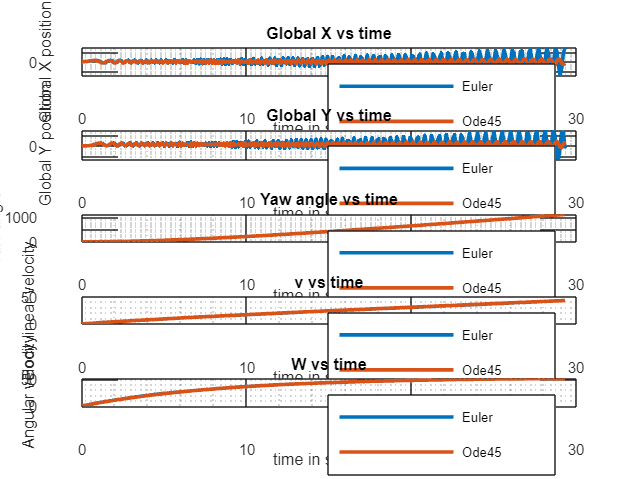

plot(t,x(4,:),t1,x1(:,4),'LineWidth',2)
xlabel('time in seconds')
ylabel('Body linear velocity')
title('v vs time')
legend('Euler','Ode45')
grid minor
subplot(5,1,5)
plot(t,x(5,:),t1,x1(:,5),'LineWidth',2)
xlabel('time in seconds')
ylabel('Angular velocity')
title('W vs time')
legend('Euler','Ode45')
grid minor

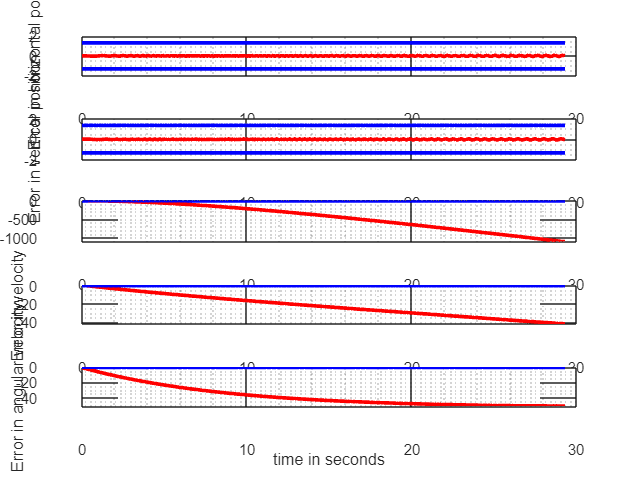


%% IMM filters
np = 4; % 4 banks of EKFs in IMM filter
R = eye(m)*r ; % Measurement noise covarince matrix isotropic homogenous measurement noise
K = [K1 K2 K3 K4;
    M1 M2 M3 M4];
Q = upsilon*q*eye(2)*upsilon'; % process noise

X_hat = zeros(n,length(t1));
P_hat = zeros(n,n,length(t1));

P0 = eye(n)*0.2; % Initial state error covariance
 B = [0 0;
     0 0;
     0 0;
     1 0;
     0 1]; % Input matrix
 H = [0 0 0 1 0;
     0 0 0 0 1];
% Inititalizations
weight = ones(np,1)/np; % Initial weight
Weight = zeros(np,length(t1)); % Weight vector
X_mix_init = zeros(n,np,length(t)); % Mixed states for each filter through out the entire time
X_hat_bank = zeros(n,np,length(t)); % states output for each filter through out the entire time -- column 1 - filter 1, column 2 - filter 2 ...
P_plus_bank(:,:,1) = P0; % 1st filter covariance 
P_plus_bank(:,:,2) = P0; % 2nd filter covariance 
P_plus_bank(:,:,3) = P0; % 3rd filter covariance 
P_plus_bank(:,:,4) = P0; % 4th filter covariance 
likelihood = zeros(1,np,length(t)); % Likelihood of measurement based on filters
P_std = zeros(n, length(t)); % Std deviation
for i = 1:length(t)
    % finding the interacting weights and normalizing sum
    weight_inter = weight.*P_tran; % Interacting model weights

    normalizing_sum = sum(weight_inter);  % normalizing factor

    % Setting the condition in case the weights are too small
    for ii = 1:np
        for j = 1:np
            if normalizing_sum(j) > 1e-20
                weight_inter(ii,j) = weight_inter(ii,j) ./ normalizing_sum(j);
            else
                normalizing_sum(j) = 0;
                weight_inter(ii,j) = 0;
            end
        end
    end
    
    % Mixed initial states and covarinnces
   
    for j = 1:np
        mixed_state = zeros(n, 1);
        cov_mixed = zeros(n,n);
        for ii = 1:np
            % mixed_state = mixed_State + w_ij * xi
            mixed_state = mixed_state + weight_inter(ii,j) * X_hat_bank(:,ii,i);
        end
        X_mix_init(:,j,i) = mixed_state;
        for ii = 1:np
            % Mixed cov = cov_mixed + weight*(filter_cov + covaraince of mixed state)
            error = X_hat_bank(:,ii,i) - X_mix_init(:,j,i);  % Mixed state error 
            cov_mixed = cov_mixed + weight_inter(ii,j)*(P_plus_bank(:,:,ii) + error*error' );
        end
        P_mixed(:,:,j) = cov_mixed;
    end

    % Output 
    y_op = y(:,i);
 
    % Individual filters -- states and covariance calculation
    for j = 1:np
        [X_hat_bank(:,j,i), P_plus_bank(:,:,j), likelihood(:,j,i)] = EKF(K(:,j), X_mix_init(:,j,i), y_op, P_mixed(:,:,j), U(:,i), dt,B, Q,R,H);
    end

   % Model Probability update
   weight = weight.*likelihood(:,:,i)';
   weight = weight/sum(weight); 
   Weight(:,i) = weight; 

   % Conditional mean and variance
   k = zeros(n,1);
   P_plus_dum = zeros(n);
   for j = 1:np
        k = k + weight(j)*X_hat_bank(:,j,i); 
   end

%    X_hat(:,i) = weight(1)*X_hat_bank(:,1,i) + weight(2)*X_hat_bank(:,2,i) + weight(3)*X_hat_bank(:,3,i) + weight(4)*X_hat_bank(:,4,i) ;
   X_hat(:,i) = k; % Updated states 
   e1 = X_hat_bank(:,1,i)-X_hat(:,i);
   e2 = X_hat_bank(:,2,i)-X_hat(:,i);
   e3 = X_hat_bank(:,3,i)-X_hat(:,i);
   e4 = X_hat_bank(:,4,i)-X_hat(:,i);
   for j = 1:np
      P_plus_dum = P_plus_dum + weight(j)*((X_hat_bank(:,j,i)-X_hat(:,i)) + P_plus_bank(:,:,j));   
       
   end
   P_hat(:,:,i) = P_plus_dum; % Updated covariance
   P_std(:,i) = (diag(P_hat(:,:,i))).^0.5; % Std deviation
%    P_hat(:,:,i) = weight(1)*(e1*e1' + P_plus_bank(:,:,1)) + weight(2)*(e2*e2' + P_plus_bank(:,:,2)) + weight(3)*(e3*e3' + P_plus_bank(:,:,3)) + weight(4)*(e4*e4' + P_plus_bank(:,:,4));
end

figure(2)
subplot(5,1,1)
plot(t,-3*P_std(1,:), 'b', t, X_hat(1,:)-x1(:,1)','r', t, 3*P_std(1,:),'b','LineWidth',2)
xlabel('time in seconds')
ylabel('Error in horizontal position')
grid minor
subplot(5,1,2)
plot(t,-3*P_std(2,:), 'b', t, X_hat(2,:)-x1(:,2)','r', t, 3*P_std(2,:),'b','LineWidth',2)
xlabel('time in seconds')
ylabel('Error in vertical position')
grid minor
subplot(5,1,3)
plot(t,-3*P_std(3,:), 'b', t, X_hat(3,:)-x1(:,3)','r', t, 3*P_std(3,:),'b','LineWidth',2)
xlabel('time in seconds')
ylabel('Error in yaw angle')
grid minor
subplot(5,1,4)
plot(t,-3*P_std(4,:), 'b', t, X_hat(4,:)-x1(:,4)','r', t, 3*P_std(4,:),'b','LineWidth',2)
xlabel('time in seconds')
ylabel('Error in velocity')
grid minor
subplot(5,1,5)
plot(t,-3*P_std(5,:), 'b', t, X_hat(5,:)-x1(:,5)','r', t, 3*P_std(5,:),'b','LineWidth',2)
xlabel('time in seconds')
ylabel('Error in angular velocity')
grid minor

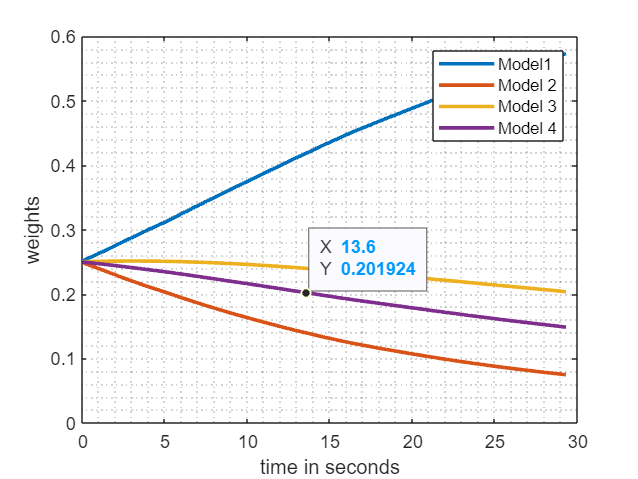


figure
plot(t, Weight, 'linewidth',2)
xlabel('time in seconds')
ylabel('weights')
legend('Model1', 'Model 2', 'Model 3', 'Model 4')
grid minor

function [X_plus, P_plus, Likelihood] = EKF(K, X_mix_init, y, P_mix_init, U, dt,B, Q,R,H)
K1 = K(1);
M1 = K(2);

 F = [0 0 -K1*X_mix_init(4)*sin(X_mix_init(3)) K1*cos(X_mix_init(3)) 0;
     0 0 K1*X_mix_init(4)*cos(X_mix_init(3)) K1*sin(X_mix_init(4)) 0;
     0 0 0 0 1;
     0 0 0 -K1 0;
     0 0 0 0 -M1]; % Jacobain matrix
xdot = [K1*X_mix_init(4)*cos(X_mix_init(3));
    K1*X_mix_init(4)*sin(X_mix_init(3));
    X_mix_init(5);
    -K1*X_mix_init(4);
    -M1*X_mix_init(5)] + B*U;
% Propagation
X_minus = X_mix_init + dt*xdot; 
F_discrete = eye(5)+dt*F;
P_minus = F_discrete*P_mix_init*F_discrete' + Q;
% Kalman gain
KG = P_minus*H'/(H*P_minus*H'+R);
% Update
X_plus = X_minus + KG*(y - H*X_minus);
P_plus = (eye(5)-KG*H)*P_minus;
% Likelihood fucntion
e = y - H*X_minus;
E = H*P_minus*H'+R;
Likelihood = ((det(2*pi*E))^0.5)*exp(-0.5*e'*(inv(E))*e);
end

function xdot = dxdt(state, Input)
% Model 1 
x = state;
K1 = 0.0763; M1 = 0.1134;
x1dot = K1*x(4)*cos(x(3));
x2dot = K1*x(4)*sin(x(3));
x3dot = x(5);
x4dot = -K1*x(4) + Input(1);
x5dot = -M1*x(5) + Input(2);

xdot = [x1dot x2dot x3dot x4dot x5dot]';
end

function xdot = odefun(t1,state,t,U, dt, q)
% Model 1 
x = state;
upsilon = [0 0;
    0 0;
    0 0;
    1 0;
    0 0];
Input1 = interp1(t,U(1,:),t1);
Input2 = interp1(t,U(2,:),t1);
K1 = 0.0763; M1 = 0.1134;
x1dot = K1*x(4)*cos(x(3));
x2dot = K1*x(4)*sin(x(3));
x3dot = x(5);

x4dot = -K1*x(4) + Input1;
x5dot = -M1*x(5) + Input2;

xdot = [x1dot x2dot x3dot x4dot x5dot]' + upsilon*sqrt(q*dt)*randn(2,1);
end



